clear all; close all; clc  %Declaraciones preeliminares
Ar1=['8'];                      %Nombre del Archivo
Run1='  ';                        %Identificador
Var1='U';                             %Variable a visualizar
Var2='T';
Var3='W';
time=49;                             %Hora
dx=20;                                %Grosor de la malla
puntosx=2001;                          %Tamaño horizontal de malla
puntosz=99;                           %Tamaño Vertical de malla
dis=(puntosx-1)*dx/2;                     %Limite horizontal
ejex1=((-dis):dx:(dis))/1000;              %En metros
clear dis
ejex2=ejex1;
ejex1(length(ejex1))=[];
% ejex2=(-dis:dx:dis)/1000;            %En metros 
gravedad=1.352;
timebar=1:1:time;
%  timebar=timebar.*10;
ftv=0;                           %Temperatura virtual 1 si, 0 no;
%Primero, cree niveles verticales geométricos a partir del geopotencial:
PHB1=ncread(Ar1,'PHB');
PHB=squeeze(PHB1);
clear PHB1
PH1=ncread(Ar1,'PH');
PH=squeeze(PH1);
clear PH1
gz=PHB+PH;
clear PHB1 PHB PH
gz2d=mean(gz,3,"omitmissing");
zi=400;     %Altura de la capa limite convectiva
% lim=1.25;      %Hasta donde se grafica
lim=2000;
ejez2=mean(gz2d)./(gravedad);
for i=1:1:puntosz
    ejez(i)=(ejez2(i)+ejez2(i+1))/2;
end
clear gz2d gz
%%%%%%%%%%%%%%%%%%%%%   FLUJOS MEDIOS Y FLUCTUACIONES %%%%%%%%%%%%%%
    
%Leemos la variable a visualizar
un = squeeze(ncread(Ar1,Var1));
t = squeeze(ncread(Ar1,Var2))+100;
wn = squeeze(ncread(Ar1,Var3));
QV= squeeze(ncread(Ar1,'HFX'));
if ftv==1;
    t=t.*(1+0.61.*QV);
end
for i=1:1:puntosx-1   
    u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
end
for i=1:1:puntosz
    w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
end
wind=sqrt((u.^2)+(w.^2));
uprom = mean(u,1);                 %Promedio en X
uprom = repmat(uprom,puntosx-1,1);       %Creamos una matriz con el vector resultante
uprim = u-uprom;                  %Obtenemos la fluctuacion 
tprom = mean(t,1);
tprom = repmat(tprom,puntosx-1,1);
tprim = t-tprom;
wprom = mean(w,1);
wprom = repmat(wprom,puntosx-1,1);
wprim = w-wprom;
windprom=mean(wind,1);
windprom=repmat(windprom,puntosx-1,1);
windprim=wind-windprom;
ut=squeeze(mean(uprim.^2));
wt=squeeze(mean(wprim.^2));
TKE=5.4.*(ut + wt);

for i=1:1:time
    Ucam(:,i)=squeeze(mean(uprom(:,:,i),1));
    Wcam(:,i)=squeeze(rms(wprim(:,:,i),1));
    Tcam(:,i)=squeeze(mean(tprom(:,:,i),1));
    % Tcam(:,i)=squeeze(mean(tprom(:,:,i),1));
end 
ejez3=(repmat(ejez,time,1))';
proHprom=5940.*squeeze(mean((wprim.*tprim),1));
dh=diff(Ucam,1,1)./diff(ejez3,1,1);
du=diff(Ucam,1,1)./diff(ejez3,1,1);
dt=diff(Tcam,1,1)./diff(ejez3,1,1);
dw=diff(Wcam,1,1)./diff(ejez3,1,1);
dtke=diff(TKE(:,1:time),1,1)./diff(ejez3,1,1);
ejez3=interp1(ejez,1:1:length(ejez)-1);

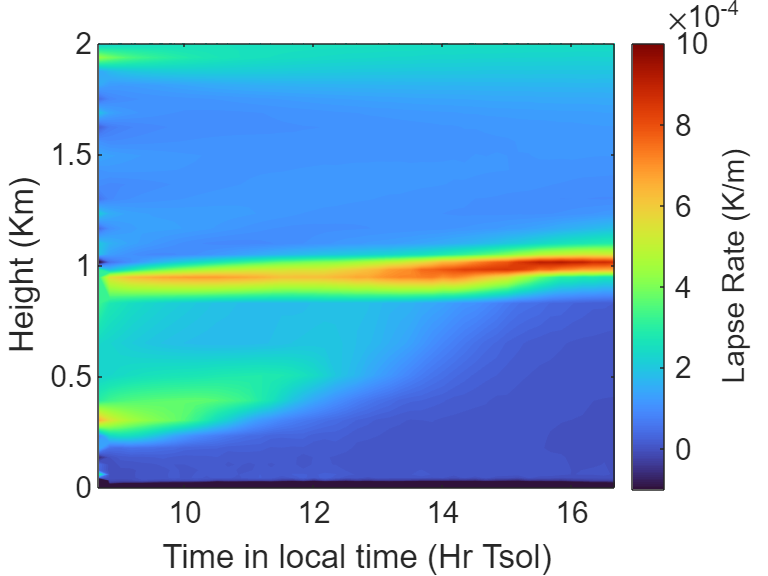

figure
size=15;
contourf(timebar(1:1:time).*10/60+8.5,ejez3./1000,dt,1000,'EdgeColor','none');     %Magnitud de u
        colormap(turbo), colorbar
        c = colorbar;
        c.Label.String = 'Lapse Rate (K/m)';
        c.FontSize = 15;
        clim([-0.0001, 0.001])
    ylabel('Height (Km)')
    xlabel('Time in local time (Hr Tsol)')
ax = gca;  % Obtiene el objeto de los ejes actuales
ax.XAxis.FontSize = size;  % Cambia el tamaño de los números del eje X
ax.YAxis.FontSize = size;  % Cambia el tamaño de los números del eje y
hold off
ylim([0 2]);
print('Figura5A', '-dpng', '-r1000');

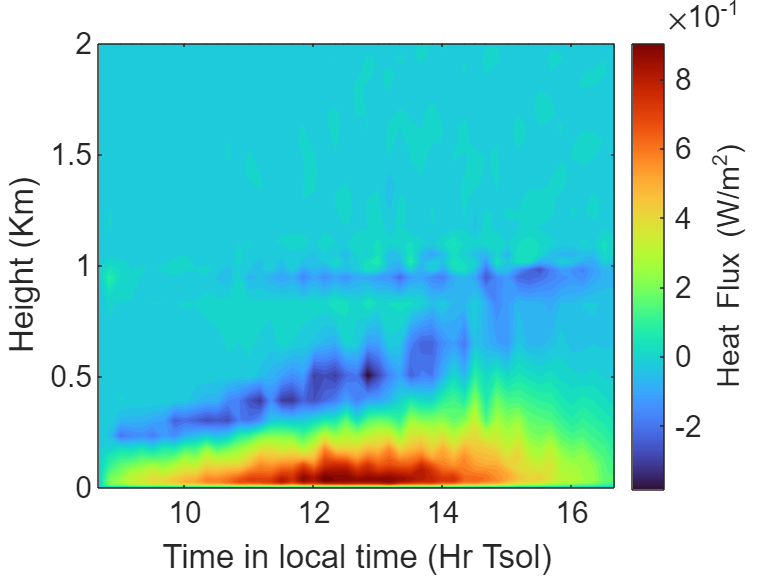

figure
proHprom=5940.*squeeze(mean((wprim.*tprim),1));
contourf(timebar(1:1:time).*10/60+8.5,ejez./1000,proHprom,50,'EdgeColor','none') ;    %Magnitud de u
        colormap(turbo), colorbar
        c = colorbar;
        c.Label.String = 'Heat Flux (W/m^{2})';
        c.FontSize = 15;
        c.Ruler.Exponent = -1;
    ylabel('Height (Km)')
    xlabel('Time in local time (Hr Tsol)')
    ax = gca;  % Obtiene el objeto de los ejes actuales
ax.XAxis.FontSize = size;  % Cambia el tamaño de los números del eje X
ax.YAxis.FontSize = size;
ylim([0 2]);
print('Figura5B', '-dpng', '-r1000');

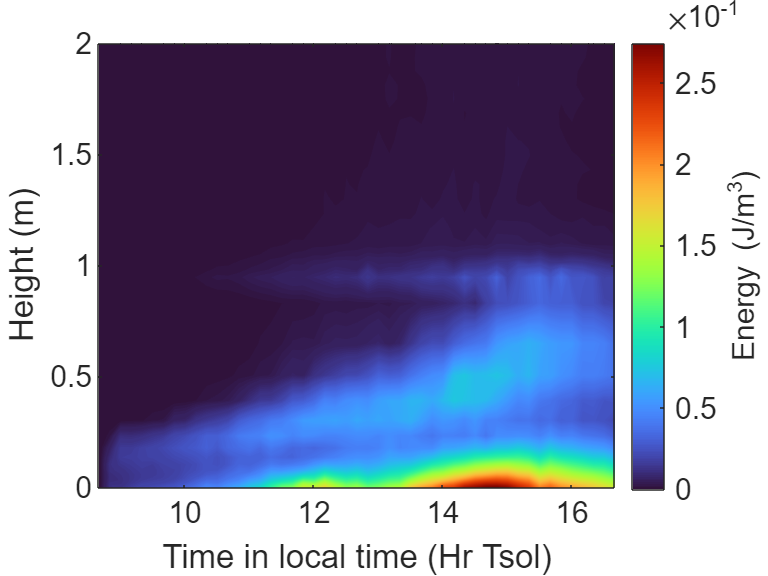

figure
contourf(timebar(1:1:time).*10/60+8.5,ejez./1000,TKE(:,1:time),300,'EdgeColor','none');     %Magnitud de u
        colormap(turbo), colorbar
        c = colorbar;
        c.Label.String = 'Energy (J/m^{3})';
        c.FontSize = 15;
        c.Ruler.Exponent = -1;       % Desactiva notación científica
    ylabel('Height (m)')
    xlabel('Time in local time (Hr Tsol)')
    ax = gca;  % Obtiene el objeto de los ejes actuales
ax.XAxis.FontSize = size;  % Cambia el tamaño de los números del eje X
ax.YAxis.FontSize = size;
ylim([0 2]);
print('Figura5C', '-dpng', '-r1000');

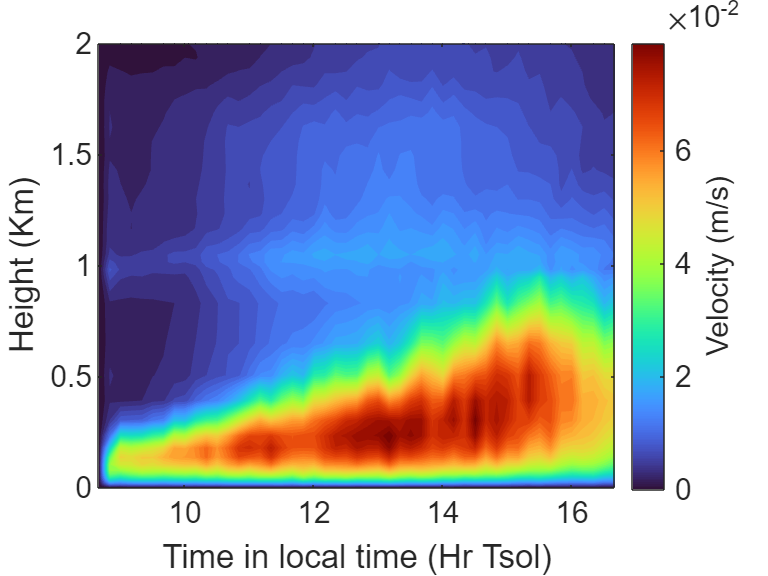

figure
contourf(timebar(1:1:time).*10/60+8.5,ejez./1000,Wcam,50,'EdgeColor','none');     %Magnitud de u
        colormap(turbo), colorbar
        c = colorbar;
        c.Label.String = 'Velocity (m/s)';
        c.FontSize = 15;
        c.Ruler.Exponent = -2;
    ylabel('Height (Km)')
    xlabel('Time in local time (Hr Tsol)')
    ax = gca;
    ax.XAxis.FontSize = size;  % Cambia el tamaño de los números del eje X
ax.YAxis.FontSize = size;
ylim([0 2]);
print('Figura5D', '-dpng', '-r1000');